Let's convert the roots of a quadratic polynomial $f(x)$ to a fixed point problem.

f = @(x) x.^2 - 4*x + 3.5;
r = roots([1 -4 3.5])

r =    2.7071e+00
   1.2929e+00


We'll define $g(x)=x-f(x)$. Intersections of its graph with the line $y=x$ are fixed points of $g$ and thus roots of $f$. (Only one is shown in the chosen plot range.) 

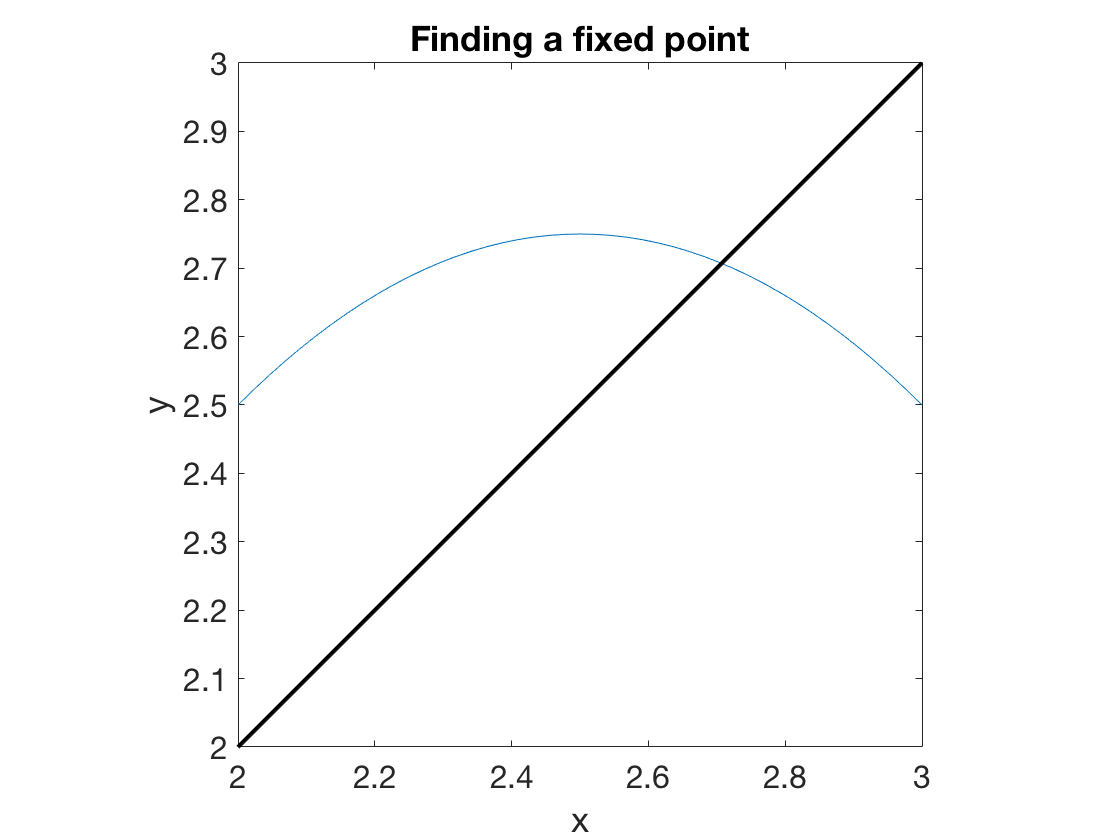

g = @(x) x - f(x);
fplot(g,[2 3])
hold on, plot([2 3],[2 3],'k')
title('Finding a fixed point'), axis equal    % ignore this line
xlabel('x'), ylabel('y')    % ignore this line

If we evalaute $g(2.1)$, we get a value of almost 2.6. 

x = 2.1;  y = g(x)

y =    2.5900e+00


So $g(x)$ is considerably closer to a fixed point than $x$ was. The value $y=g(x)$ ought to become our new $x$ value! Changing the $x$ coordinate in this way is the same as following a horizontal line over to the graph of $y=x$.

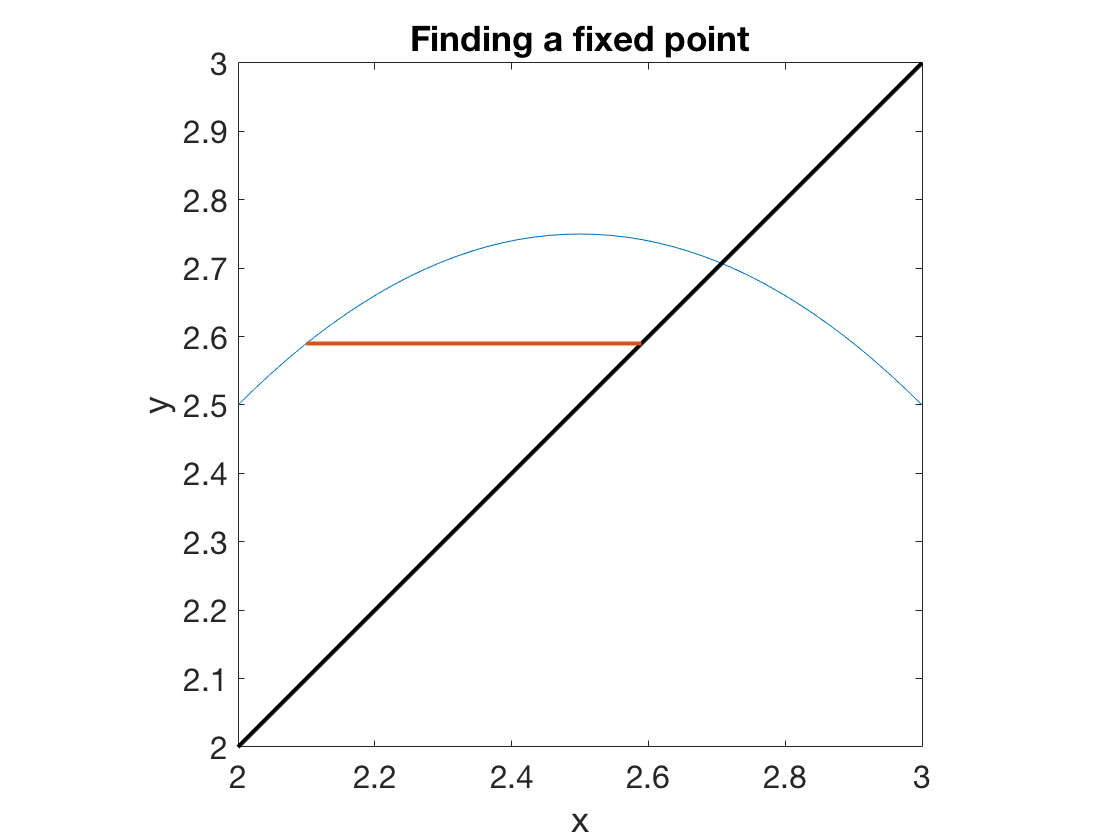

plot([x y],[y y],'-')

x = y;

Now we can compute a new value for $y$. We leave $x$ alone here, so we travel along a vertical line to the graph of $g$.

y = g(x)

y =    2.7419e+00


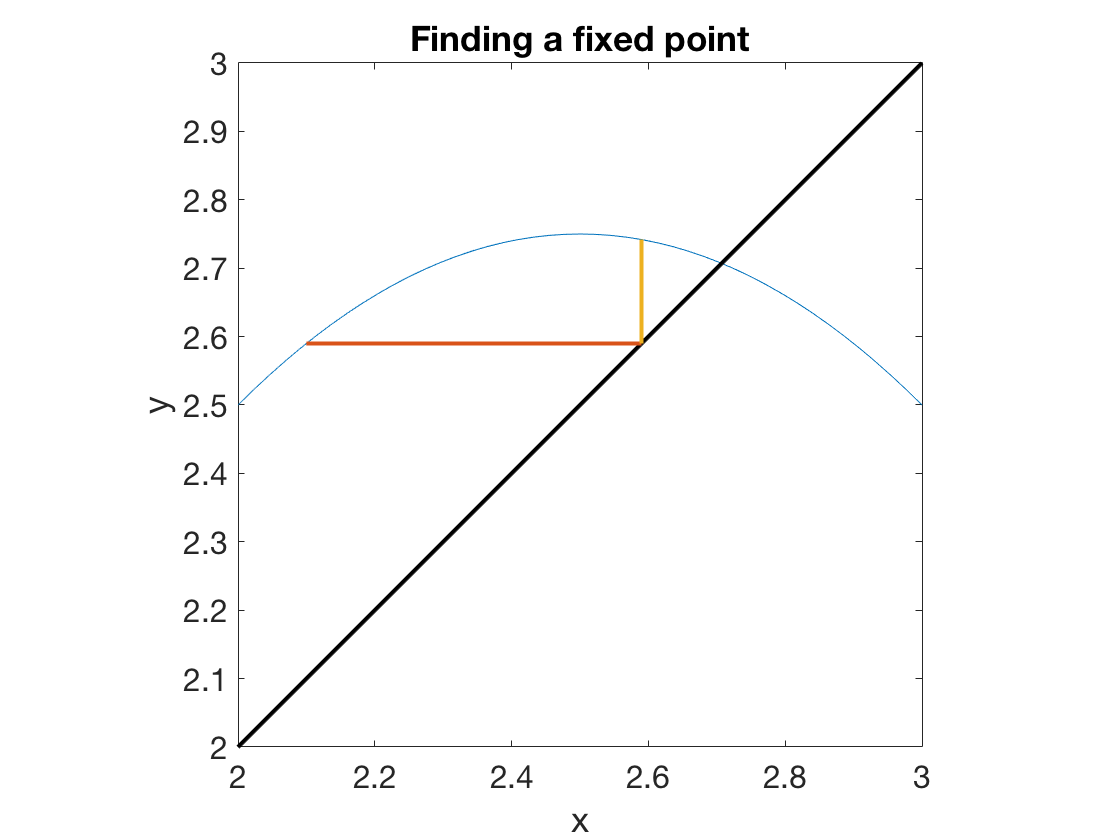

plot([x x],[x y],'-')

You see that we are in a position to repeat these steps as often as we like. Let's apply them a few times and see the result. 

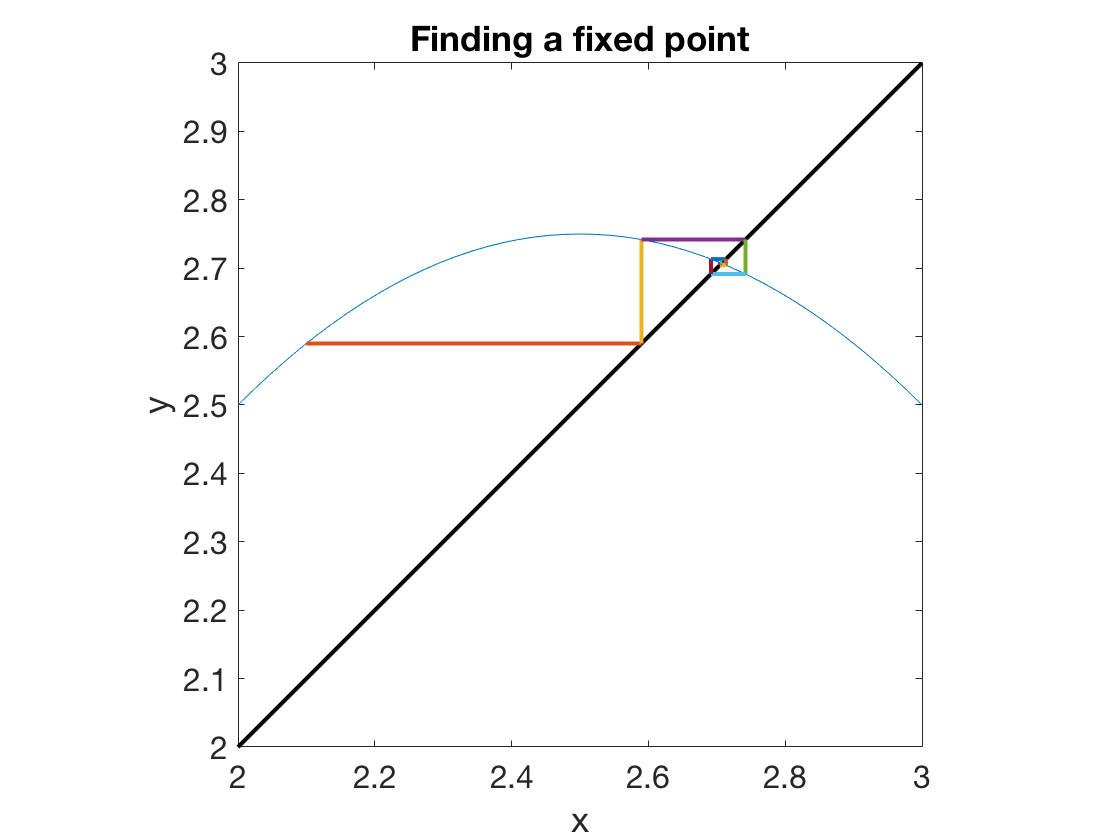

for k = 1:5
    plot([x y],[y y],'-'),  x = y;    % y --> new x
    y = g(x);  plot([x x],[x y],'-')  % g(x) --> new y
end

The process spirals in beautifully toward the fixed point we seek. Our last estimate has almost 4 accurate digits.

abs(y-r(1))/r(1)

ans =    1.6531e-04


Now let's try to find the other fixed point in the same way. We'll use 1.3 as a starting approximation.

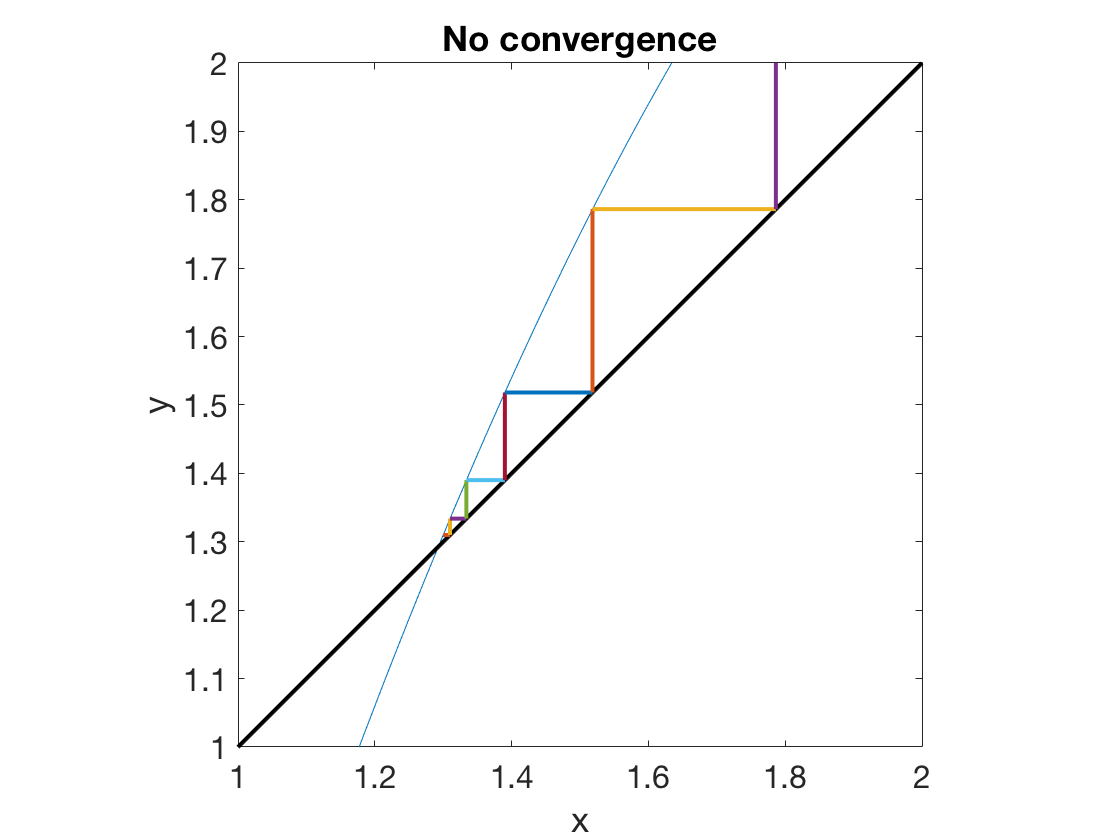

cla
fplot(g,[1 2])
hold on, plot([1 2],[1 2],'k'), ylim([1 2])
x = 1.3; y = g(x);
for k = 1:5
    plot([x y],[y y],'-'),  x = y;    % y --> new x
    y = g(x);  plot([x x],[x y],'-')  % g(x) --> new y
end
title('No convergence')    % ignore this line

We started near the true fixed point, which is at about 1.293. But this time, the iteration is pushing us *away* from the correct answer. 